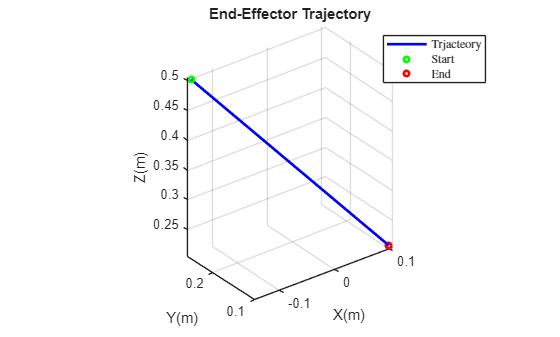

clc; clear; close all

global robot gains tdom N friction torque

% Robot parameters
robot.mass = [0.2 0.1 0.2 0.1]*20;
robot.l    = [0.25 0.15 0.25 0.15];
robot.r    = robot.l/2;
robot.Iz   = [0.1 0.1 0.1 0.1]*0.002;   % renamed to Iz to match dynamics
robot.tormax = 8;


m = [0.4; 0.2; 0.2; 0.1];
L = [0.25; 0.15; 0.25; 0.15];
r = [0.125; 0.075; 0.125; 0.075];
I = [0.002; 0.0002; 0.002; 0.002];

m1 = m(1);
m2 = m(2);
m3 = m(3);
m4 = m(4);

% Define State Variables
theta = sym('theta',[4 1]);
d_theta = sym('theta_d',[4 1]);
X = [theta; d_theta];

% Auxilary Functions
p1 = I(1)+I(2)+I(3)+I(4)+(m(1)*r(1)^2)...
    +(m(3)*r(3)^2)+(L(1)^2*(m(1)+m(2)))...
    +((L(1)^2+L(2)^2)*(m(4)+m(3)))...
    +(2*((L(1)*m(1)*r(1))+(L(3)*m(3)*r(3))));

p2 = 2*L(1)*L(2)*(m(3)+m(4))+L(1)*m(3)*r(3);

p3 = I(3)+I(4)+m(2)*r(2)^2+L(2)^2*(m(2)+m(3)+m(4))...
    +2*L(3)*m(3)*r(3);

p4 = m(3)+m(4);

p5 = I(4);

p6 = (L(3)*m(3)+L(3)*m(4)+m(3)*r(3))*L(1)*sin(theta(3));


% Dynamics
M = [p1+p2*cos(theta(3))     0   p3+0.5*p2*cos(theta(3)) p5
            0                p4            0             0
     p3+0.5*p2*cos(theta(3)) 0             p3            p5
            p5               0             p5            p5];

C = [-d_theta(3)    0 -(d_theta(1)+d_theta(3))*p6 0
          0         0               0             0
     d_theta(1)*p6  0               0             0
          0         0               0             0];

G = [0; 9.81*(m2+m3+m4); 0; 0];

f = [d_theta; M \ (-C*d_theta-G)];

g = [ zeros(4,4); inv(M) ];


% Constraints
v_ub = [1; 1; 1; 5];
v_lb = -v_ub;

% Barrier functions
h1 = v_ub(1)^2 - d_theta(1)^2;
h2 = v_ub(2)^2 - d_theta(2)^2;
h3 = v_ub(3)^2 - d_theta(3)^2;
h4 = v_ub(4)^2 - d_theta(4)^2;

%% Lie derivatives
Lf_h1 = jacobian(h1,X)*f;
Lg_h1 = jacobian(h1,X)*g;

Lf_h2 = jacobian(h2,X)*f;
Lg_h2 = jacobian(h2,X)*g;

Lf_h3 = jacobian(h3,X)*f;
Lg_h3 = jacobian(h3,X)*g;

Lf_h4 = jacobian(h4,X)*f;
Lg_h4 = jacobian(h4,X)*g;

%% Generate MATLAB functions
matlabFunction(h1,    'File','h1_fun',    'Vars',{X});
matlabFunction(Lf_h1, 'File','Lf_h1_fun', 'Vars',{X});
matlabFunction(Lg_h1, 'File','Lg_h1_fun', 'Vars',{X});

matlabFunction(h2,    'File','h2_fun',    'Vars',{X});
matlabFunction(Lf_h2, 'File','Lf_h2_fun', 'Vars',{X});
matlabFunction(Lg_h2, 'File','Lg_h2_fun', 'Vars',{X});

matlabFunction(h3,    'File','h3_fun',    'Vars',{X});
matlabFunction(Lf_h3, 'File','Lf_h3_fun', 'Vars',{X});
matlabFunction(Lg_h3, 'File','Lg_h3_fun', 'Vars',{X});

matlabFunction(h4,    'File','h4_fun',    'Vars',{X});
matlabFunction(Lf_h4, 'File','Lf_h4_fun', 'Vars',{X});
matlabFunction(Lg_h4, 'File','Lg_h4_fun', 'Vars',{X});

%% Time settings
N  = 2000;
tf = 2;
tdom.dt = tf/(N-1);
tspan = linspace(0,tf,N);




%% End-effector trajectory
x1 = -0.14; x2 = 0.10;
y1 =  0.26; y2 = 0.10;
z1 =  0.50; z2 = 0.21;

rtraj = 10*(tspan/tf).^3 - 15*(tspan/tf).^4 + 6*(tspan/tf).^5;

x = x1 + rtraj*(x2-x1);
y = y1 + rtraj*(y2-y1);
z = z1 + rtraj*(z2-z1);

%% Desired joint trajectory from inverse kinematics
q = inverse_4dof_matrix([x' y' z'], robot.l, N);
q(:,4) = 2*pi*rtraj';   % desired wrist rotation

dq = diff(q)/tdom.dt;
dq(N,:) = dq(N-1,:);

tdom.Qd  = q;
tdom.dQd = dq;

tdom.ddQd = diff(tdom.dQd)/tdom.dt;
tdom.ddQd(end+1,:) = tdom.ddQd(end,:);


Qd_sim  = [tspan(:)  tdom.Qd];
dQd_sim = [tspan(:)  tdom.dQd];
ddQd_sim = [tspan(:) tdom.ddQd];

%

x0 =  [tdom.Qd(1,:)';tdom.dQd(1,:)'];

v =  [tdom.Qd(end,:)'];
dv = [tdom.dQd(end,:)'];

theta0 = x0(1:4)*180/pi;
theta_ss = v*180/pi;

figure
hold on
grid on
plot3(x, y, z, 'b', 'LineWidth', 2)
plot3(x(1), y(1), z(1), 'go', 'MarkerSize', 4, 'LineWidth', 2)
plot3(x(end), y(end), z(end), 'ro', 'MarkerSize', 4, 'LineWidth', 2)

axis equal
view(3)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')

title('End-Effector Trajectory')

legend('Trjacteory', 'Start', 'End','Location','best', 'Interpreter','latex');hold off

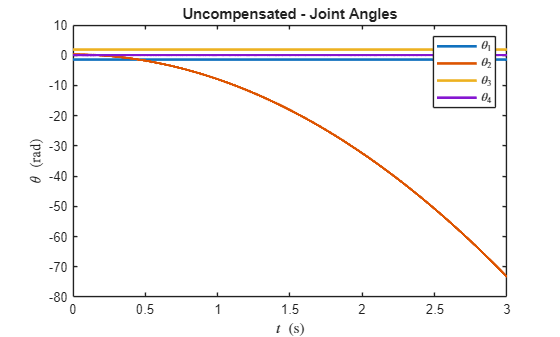





Simulation = sim('ECEN_5738_Project_sim');

t = Simulation.tout;

% State Vectors for each controller
x_nom      = Simulation.x.Data;
x_PD       = Simulation.x_PD.Data;
x_SMC      = Simulation.x_SMC.Data;
x_BackStep = Simulation.x_BackStep.Data;
x_CBF      = Simulation.x_CBF.Data;

% End Effector Trajectories for each controller
pos_nom      = forward_4dof(x_nom(:,1:4), robot.l);
pos_PD       = forward_4dof(x_PD(:,1:4), robot.l);
pos_SMC      = forward_4dof(x_SMC(:,1:4), robot.l);
pos_BackStep = forward_4dof(x_BackStep(:,1:4), robot.l);
pos_CBF      = forward_4dof(x_CBF(:,1:4), robot.l);

% error for each controller
e_PD       = Simulation.e_PD.Data;
e_SMC      = Simulation.e_SMC.Data;
e_BackStep = Simulation.e_BackStep.Data;
e_CBF      = Simulation.e_CBF.Data;

% Uncompensated System

plot(t, x_nom(:,1:4),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\theta\ \mathrm{(rad)}$', 'Interpreter','latex')
title('Uncompensated - Joint Angles')
legend('$\theta_1$','$\theta_2$','$\theta_3$','$\theta_4$','location','ne','Interpreter','latex')

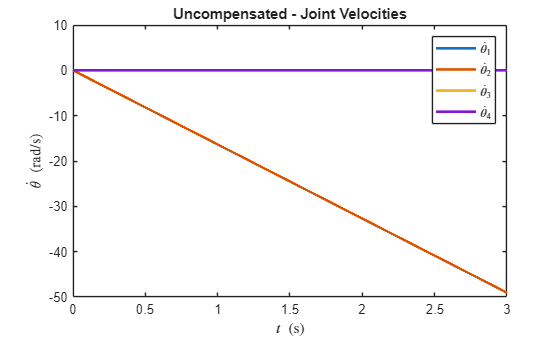


plot(t, x_nom(:,5:8),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\dot{\theta}\ \mathrm{(rad/s)}$', 'Interpreter','latex')
title('Uncompensated - Joint Velocities')
legend({'$\dot{\theta}_1$', '$\dot{\theta}_2$', '$\dot{\theta}_3$', '$\dot{\theta}_4$'},'Interpreter','latex');

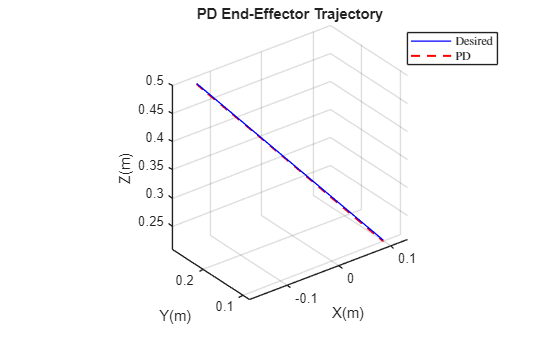


% PD Control Simulations
figure
hold on
grid on
plot3(x, y, z, 'b', 'LineWidth', 1)
plot3(pos_PD(:,1),   pos_PD(:,2),   pos_PD(:,3),   'r--', 'LineWidth', 1.5)
axis equal
view(3)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
title('PD End-Effector Trajectory')
legend('Desired', 'PD','Location','best', 'Interpreter','latex');hold off

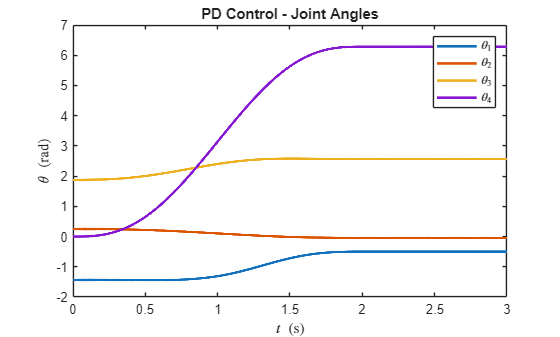


plot(t, x_PD(:,1:4),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\theta\ \mathrm{(rad)}$', 'Interpreter','latex')
title('PD Control - Joint Angles')
legend('$\theta_1$','$\theta_2$','$\theta_3$','$\theta_4$','location','ne','Interpreter','latex')

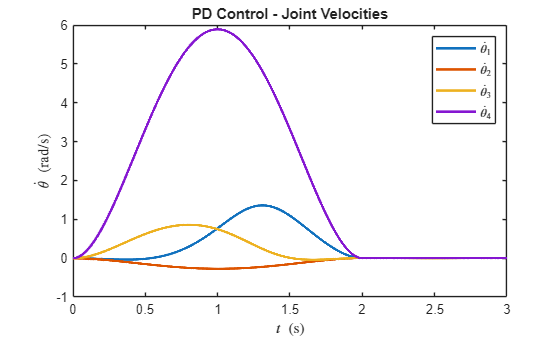



plot(t, x_PD(:,5:8),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\dot{\theta}\ \mathrm{(rad/s)}$', 'Interpreter','latex')
title('PD Control - Joint Velocities')
legend({'$\dot{\theta}_1$', '$\dot{\theta}_2$', '$\dot{\theta}_3$', '$\dot{\theta}_4$'},'Interpreter','latex');

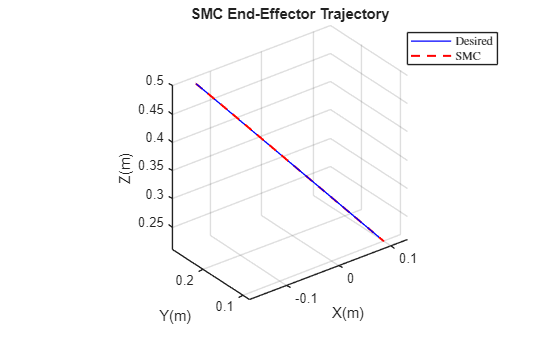


%SMC Simulations
figure
hold on
grid on
plot3(x, y, z, 'b', 'LineWidth', 1)
plot3(pos_SMC(:,1),   pos_SMC(:,2),   pos_SMC(:,3),   'r--', 'LineWidth', 1.5)
axis equal
view(3)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
title('SMC End-Effector Trajectory')
legend('Desired', 'SMC','Location','best', 'Interpreter','latex');hold off

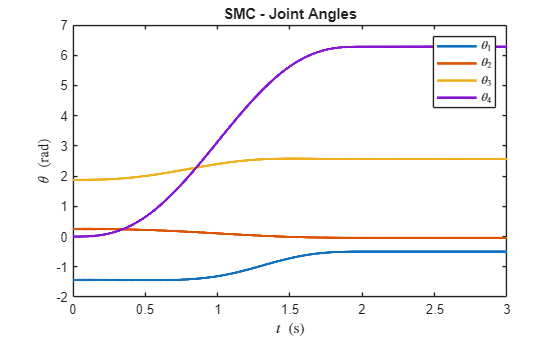


plot(t, x_SMC(:,1:4),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\theta\ \mathrm{(rad)}$', 'Interpreter','latex')
title('SMC - Joint Angles')
legend('$\theta_1$','$\theta_2$','$\theta_3$','$\theta_4$','location','ne','Interpreter','latex')

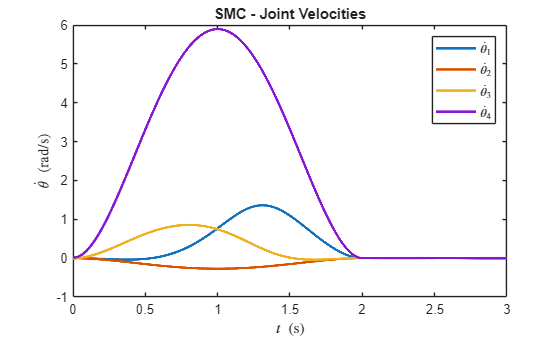


plot(t, x_SMC(:,5:8),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\dot{\theta}\ \mathrm{(rad/s)}$', 'Interpreter','latex')
title('SMC - Joint Velocities')
legend({'$\dot{\theta}_1$', '$\dot{\theta}_2$', '$\dot{\theta}_3$', '$\dot{\theta}_4$'},'Interpreter','latex');

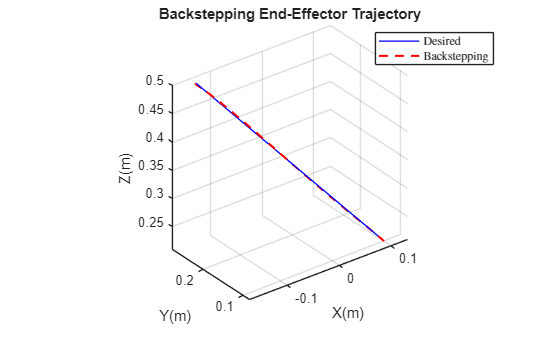



%Backstepping Simulations
figure
hold on
grid on
plot3(x, y, z, 'b', 'LineWidth', 1)
plot3(pos_BackStep(:,1),   pos_BackStep(:,2),   pos_BackStep(:,3),   'r--', 'LineWidth', 1.5)
axis equal
view(3)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
title('Backstepping End-Effector Trajectory')
legend('Desired', 'Backstepping','Location','best', 'Interpreter','latex');hold off

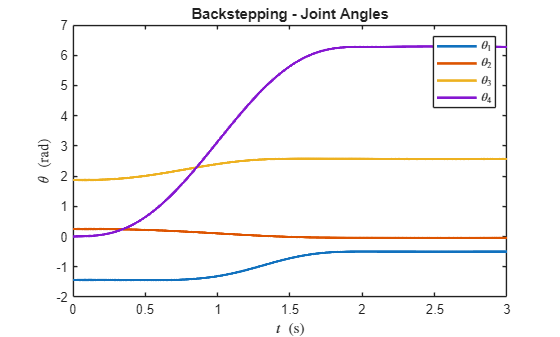


plot(t, x_BackStep(:,1:4),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\theta\ \mathrm{(rad)}$', 'Interpreter','latex')
title('Backstepping - Joint Angles')
legend('$\theta_1$','$\theta_2$','$\theta_3$','$\theta_4$','location','ne','Interpreter','latex')

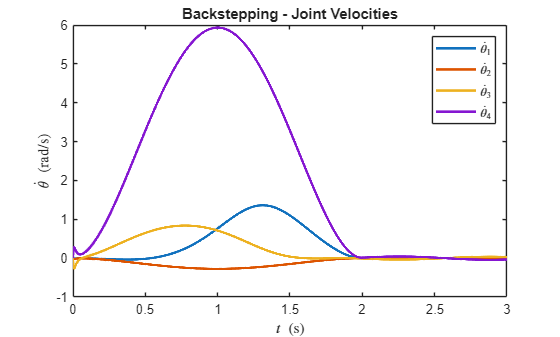

plot(t, x_BackStep(:,5:8),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\dot{\theta}\ \mathrm{(rad/s)}$', 'Interpreter','latex')
title('Backstepping - Joint Velocities')
legend({'$\dot{\theta}_1$', '$\dot{\theta}_2$', '$\dot{\theta}_3$', '$\dot{\theta}_4$'},'Interpreter','latex');

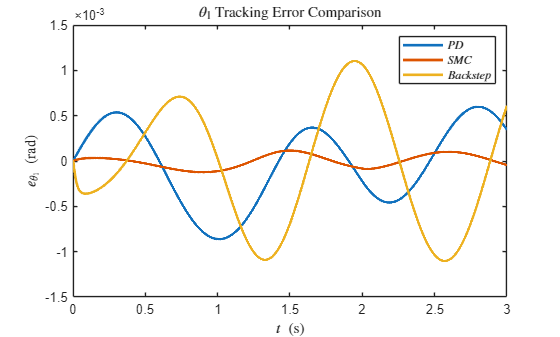


plot(t, e_PD(:,1),'LineWidth',2);
hold on
plot(t, e_SMC(:,1),'LineWidth',2);
plot(t, e_BackStep(:,1),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter', 'latex')
ylabel('$e_{\theta_1}\ \mathrm{(rad)}$', 'Interpreter', 'latex')
title('$\theta_1$ Tracking Error Comparison','Interpreter','latex')
legend('$PD$','$SMC$','$Backstep$','Interpreter', 'latex', 'Location', 'ne'); hold off

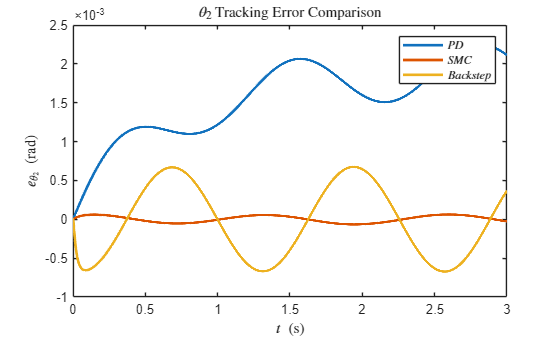


plot(t, e_PD(:,2),'LineWidth',2);
hold on
plot(t, e_SMC(:,2),'LineWidth',2);
plot(t, e_BackStep(:,2),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter', 'latex')
ylabel('$e_{\theta_2}\ \mathrm{(rad)}$', 'Interpreter', 'latex')
title('$\theta_2$ Tracking Error Comparison','Interpreter','latex')
legend('$PD$','$SMC$','$Backstep$','Interpreter', 'latex', 'Location', 'ne'); hold off

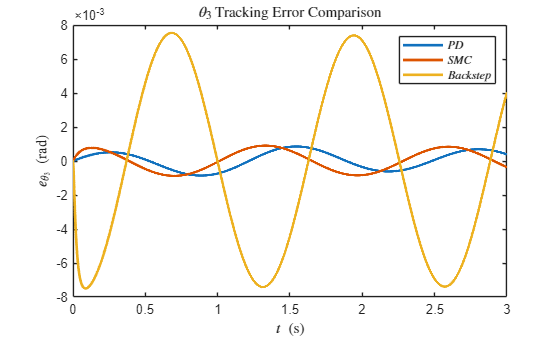


plot(t, e_PD(:,3),'LineWidth',2);
hold on
plot(t, e_SMC(:,3),'LineWidth',2);
plot(t, e_BackStep(:,3),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter', 'latex')
ylabel('$e_{\theta_3}\ \mathrm{(rad)}$', 'Interpreter', 'latex')
title('$\theta_3$ Tracking Error Comparison','Interpreter','latex')
legend('$PD$','$SMC$','$Backstep$','Interpreter', 'latex', 'Location', 'ne'); hold off

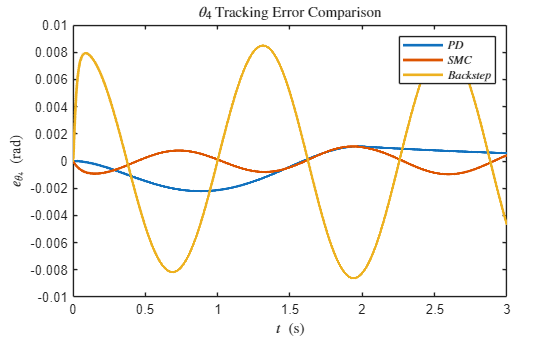


plot(t, e_PD(:,4),'LineWidth',2);
hold on
plot(t, e_SMC(:,4),'LineWidth',2);
plot(t, e_BackStep(:,4),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter', 'latex')
ylabel('$e_{\theta_4}\ \mathrm{(rad)}$', 'Interpreter', 'latex')
title('$\theta_4$ Tracking Error Comparison','Interpreter','latex')
legend('$PD$','$SMC$','$Backstep$','Interpreter', 'latex', 'Location', 'ne')

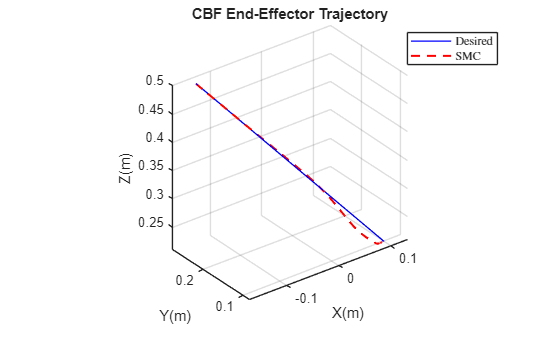


% CBF Simulations
figure
hold on
grid on
plot3(x, y, z, 'b', 'LineWidth', 1)
plot3(pos_CBF(:,1),   pos_SMC(:,2),   pos_SMC(:,3),   'r--', 'LineWidth', 1.5)
axis equal
view(3)
xlabel('X(m)')
ylabel('Y(m)')
zlabel('Z(m)')
title('CBF End-Effector Trajectory')
legend('Desired', 'SMC','Location','best', 'Interpreter','latex');hold off

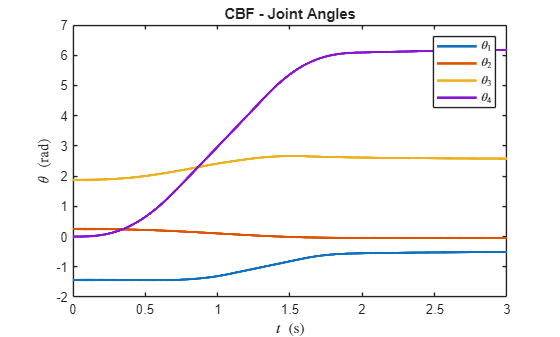


plot(t, x_CBF(:,1:4),'LineWidth',2)
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\theta\ \mathrm{(rad)}$', 'Interpreter','latex')
title('CBF - Joint Angles')
legend('$\theta_1$','$\theta_2$','$\theta_3$','$\theta_4$','location','ne','Interpreter','latex')

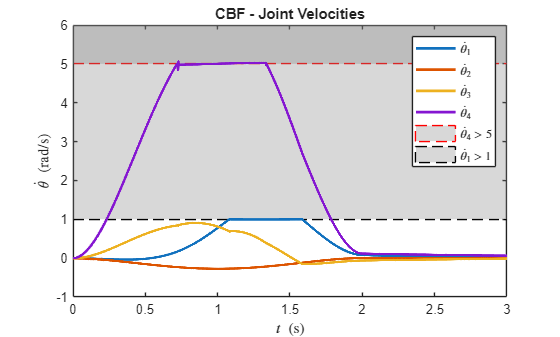


plot(t, x_CBF(:,5:8),'LineWidth',2)
yregion(v_ub(4),Inf,'EdgeColor','r','LineStyle','--')
yregion(v_ub(1),Inf,'EdgeColor','k','LineStyle','--')
xlabel('$t\ \mathrm{(s)}$', 'Interpreter','latex')
ylabel('$\dot{\theta}\ \mathrm{(rad/s)}$', 'Interpreter','latex')
title('CBF - Joint Velocities')
legend({'$\dot{\theta}_1$', '$\dot{\theta}_2$', '$\dot{\theta}_3$', '$\dot{\theta}_4$','$\dot{\theta}_4 > 5$','$\dot{\theta}_1$ > 1'},'Interpreter','latex');


%%%%% The following functions are from the paper:
%%%%% https://rshare.library.torontomu.ca/articles/thesis/Adaptive_PD_Sliding_Mode_Control_For_4_DOF_SCARA_Variant/14656593?file=28138440
function angle = inverse_4dof_matrix(pos,l,N) 
for i = 1:N
    x = pos(i,1);
    y = pos(i,2);
    z = pos(i,3);

    angle(i,2) = z - 0.25;

    cos3 = (x^2 + y^2 - l(1)^2 - l(3)^2)/(2*l(1)*l(3));
    cos3 = max(min(cos3,1),-1);   
    sin13 = sqrt(1-cos3^2);

    angle(i,3) = atan2(sin13,cos3);

    xx  = atan2(x,y);
    yy1 = atan2(l(3)*sin(angle(i,3)), l(1)+l(3)*cos(angle(i,3)));
    angle(i,1) = xx - yy1;

    angle(i,4) = 0;
end
end


function pos = forward_4dof(q,l)
pos(:,2) = l(3)*cos(q(:,1)+q(:,3)) + l(1)*cos(q(:,1));
pos(:,1) = l(3)*sin(q(:,1)+q(:,3)) + l(1)*sin(q(:,1));
pos(:,3) = q(:,2) + 0.25;
end